# Multiresolution Analysis (MRA)

## Empirical Wavelet Transform (EWT)

% clear; clc; close all;
% format short eng
% % Plot Colors
% LUCopper = [147, 86, 14]/255;
% LUCopper_Light = [225, 213, 199]/255;
% LUBlue = [17, 55, 125]/255;
% LUBlue_Light = [197, 204, 221]/255;
% Red_Dark = [192, 0, 0]/255;
% Red_Light = [235, 200, 197]/255;
% pink = [255, 199, 206]/255;


## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

load('E2038.mat');   % Suppose data is in a variable pz
% % % % % % % % % % % % % % % % % % % % % % % 
%  Test Mean-subtraction to remove DC offset/baseline
dataTest1 = p(:,1) - mean(p(1:100,1));
dataTest2 = p(:,2) - mean(p(1:100,2));
dataTest3 = p(:,3) - mean(p(1:100,3));
dataTest4 = p(:,4) - mean(p(1:100,4));
dataTest5 = p(:,5) - mean(p(1:100,5));
dataTest6 = p(:,6) - mean(p(1:100,6));
dataTest7 = p(:,7) - mean(p(1:100,7));
dataTest8 = p(:,8) - mean(p(1:100,8));
dataTest9 = p(:,9) - mean(p(1:100,9));
dataTest10 = p(:,10) - mean(p(1:100,10));
dataTest11= p(:,11) - mean(p(1:100,11));
dataTest12 = p(:,12) - mean(p(1:100,12));

% % % % % % % % % % % % % % % % % % % % 
data = dataTest3;    % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;

Use ewt to obtain a multiresolution analysis (MRA) of the signal, and the corresponding analysis coefficients. Use the four largest peaks to determine the filter passbands. Plot the signal and the MRA components.

Processing Test 1...


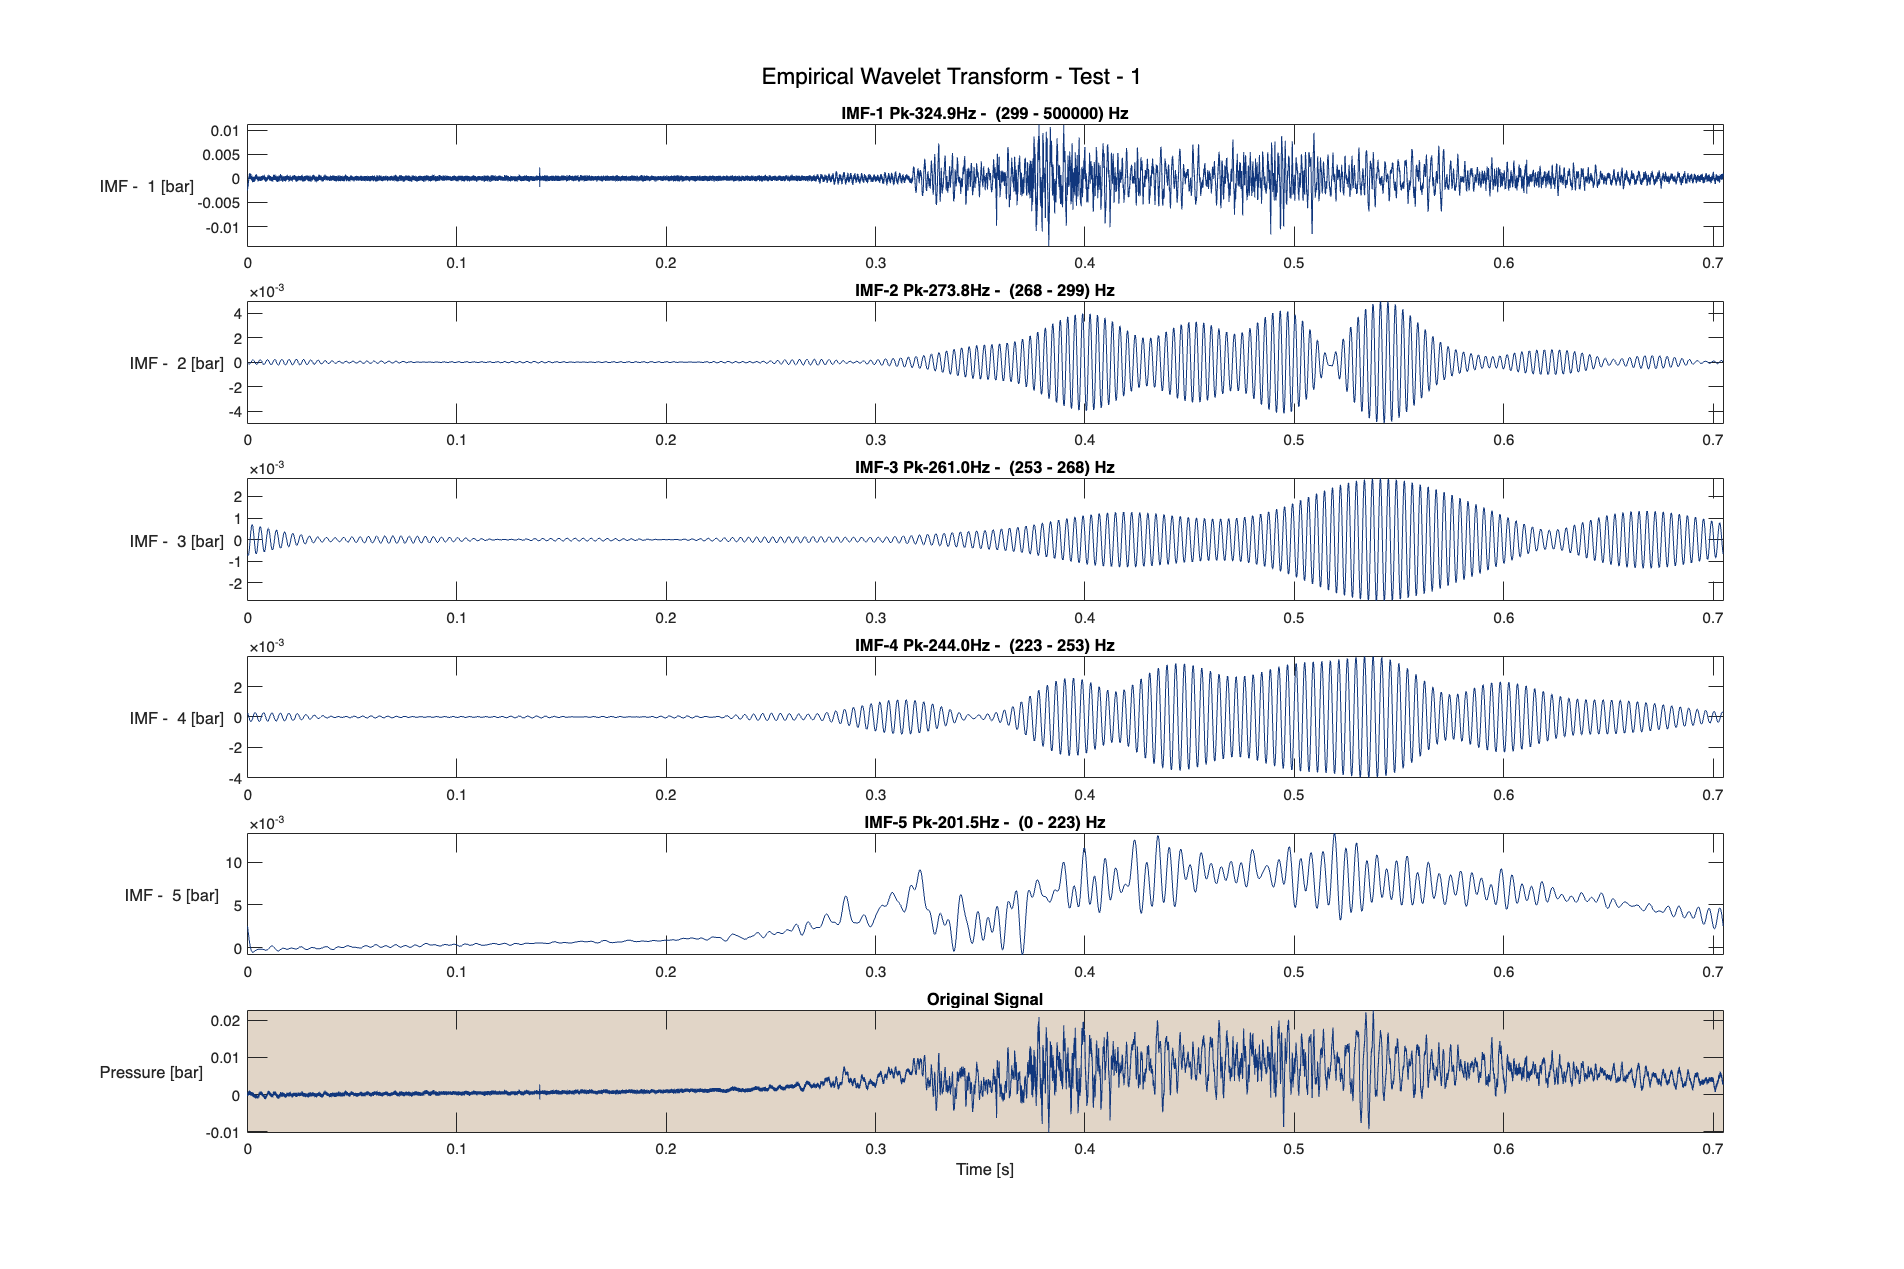

Processing Test 2...


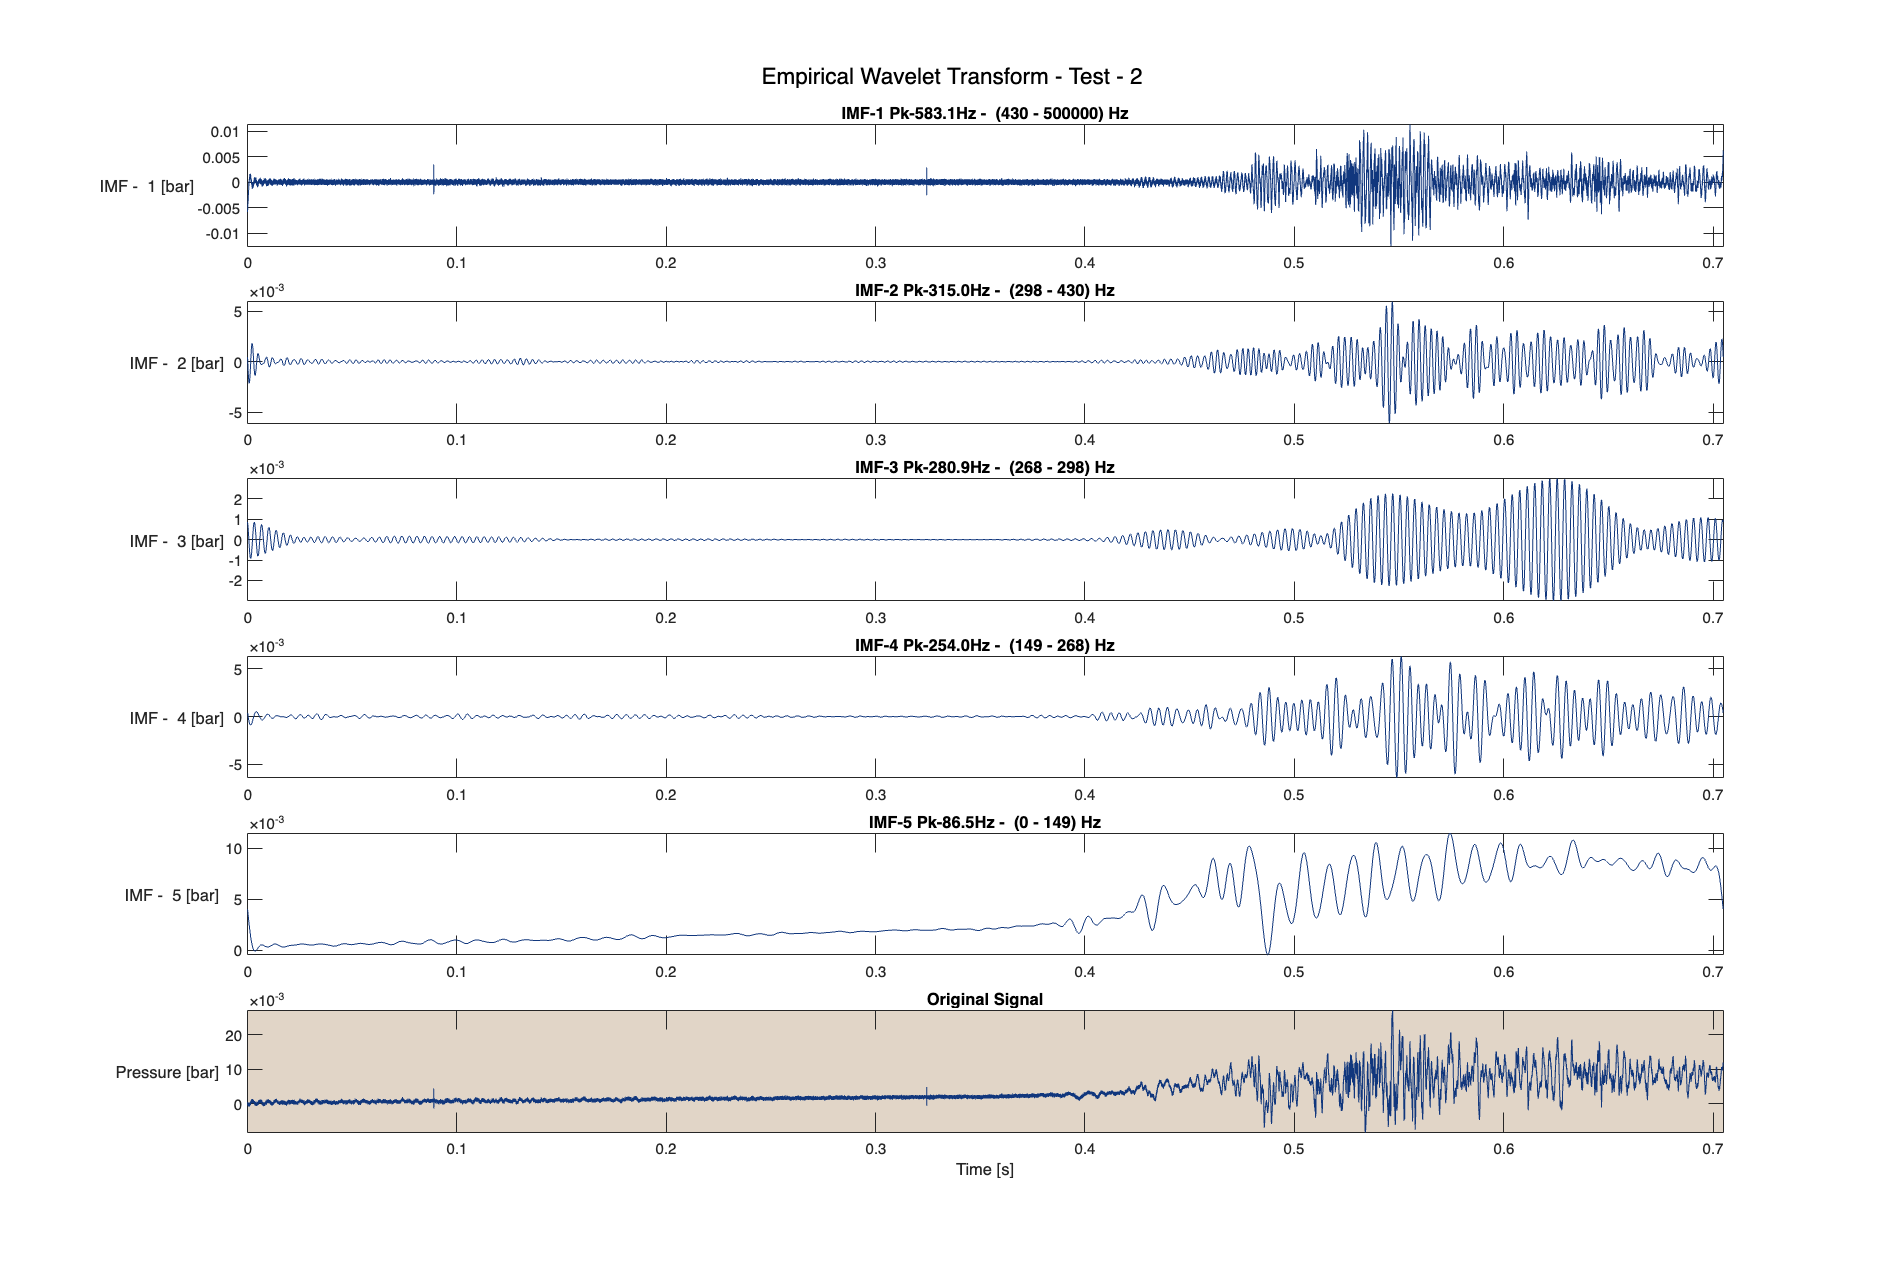

Processing Test 3...


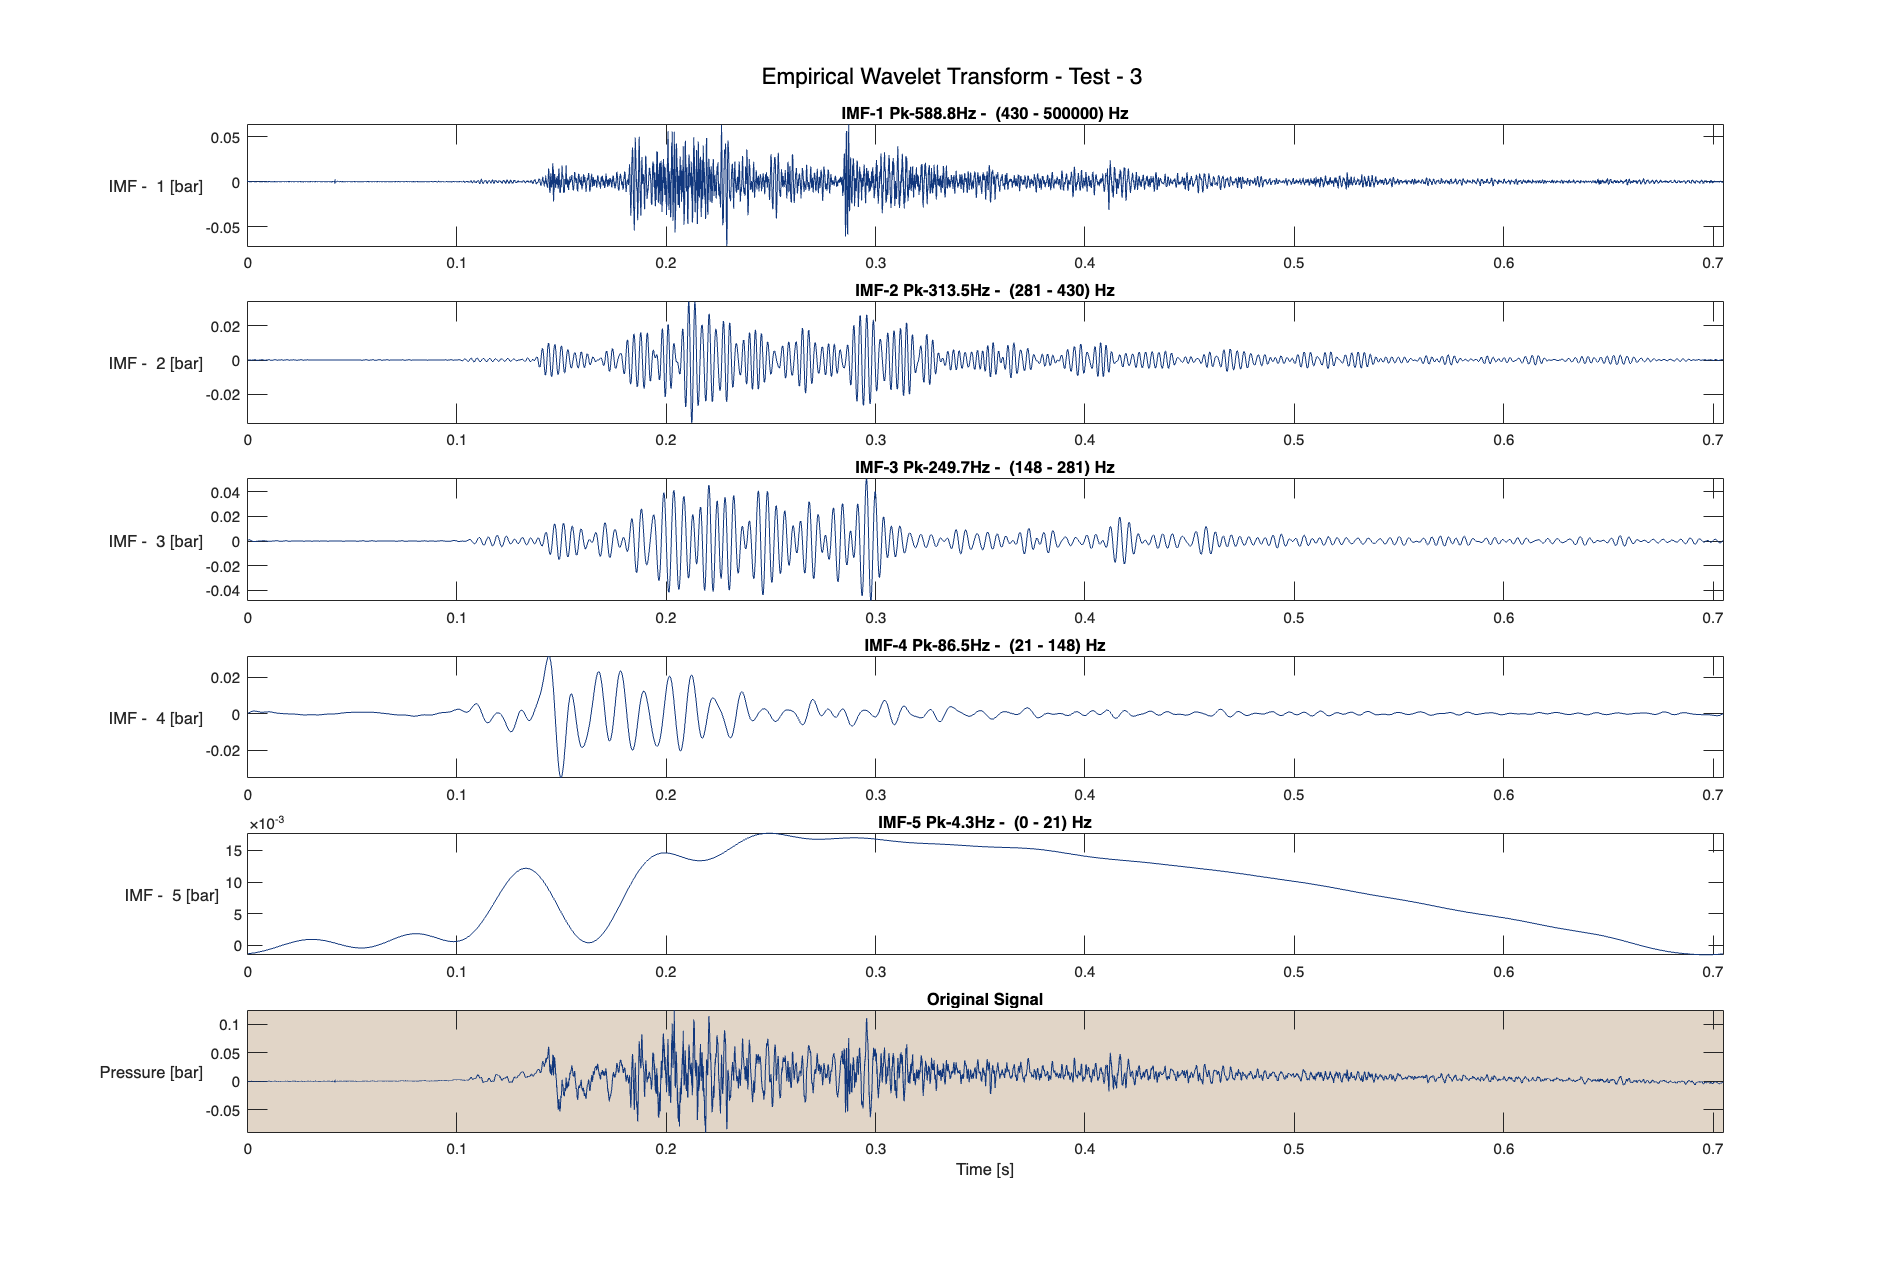

Processing Test 4...


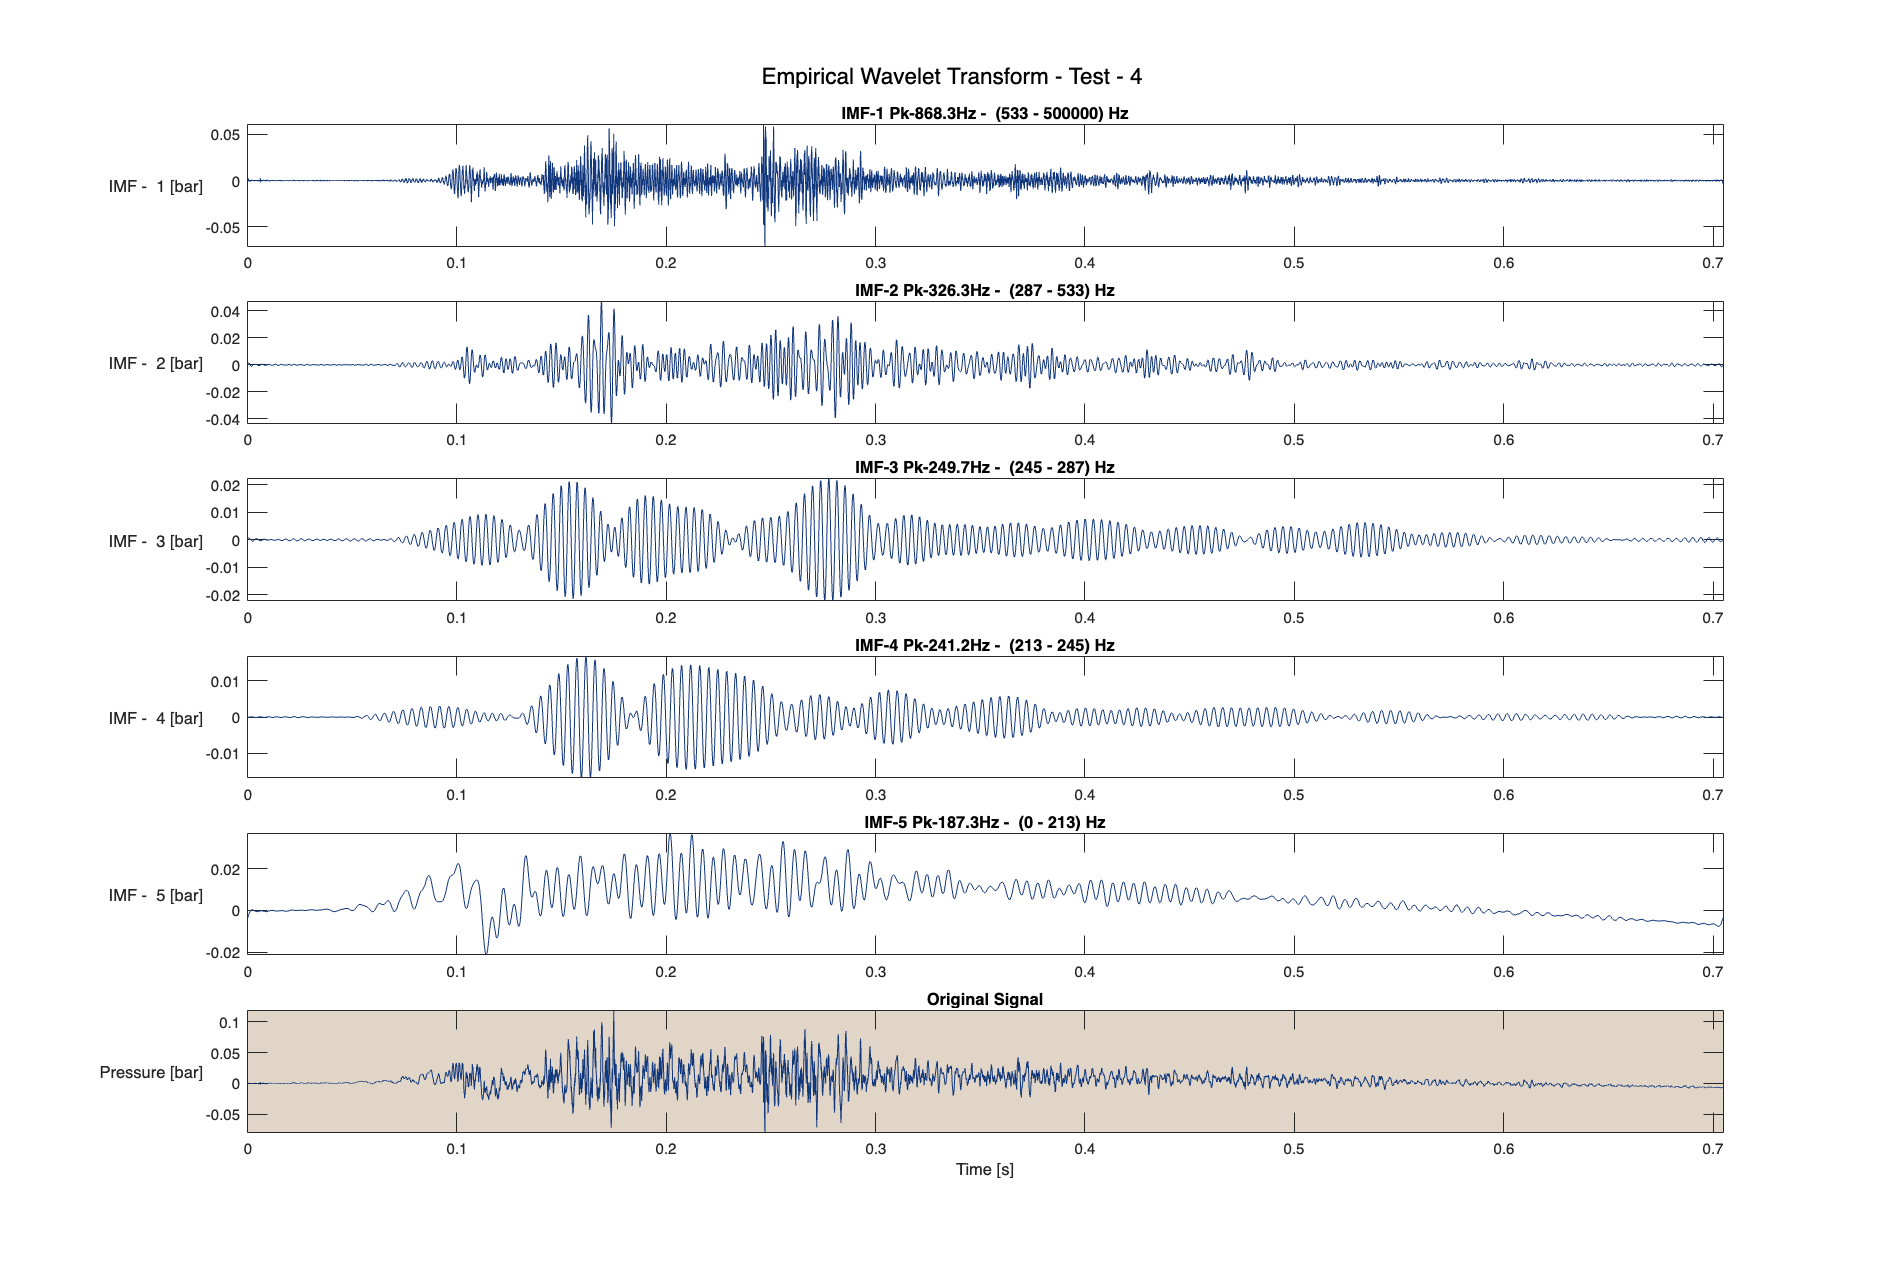

Processing Test 5...


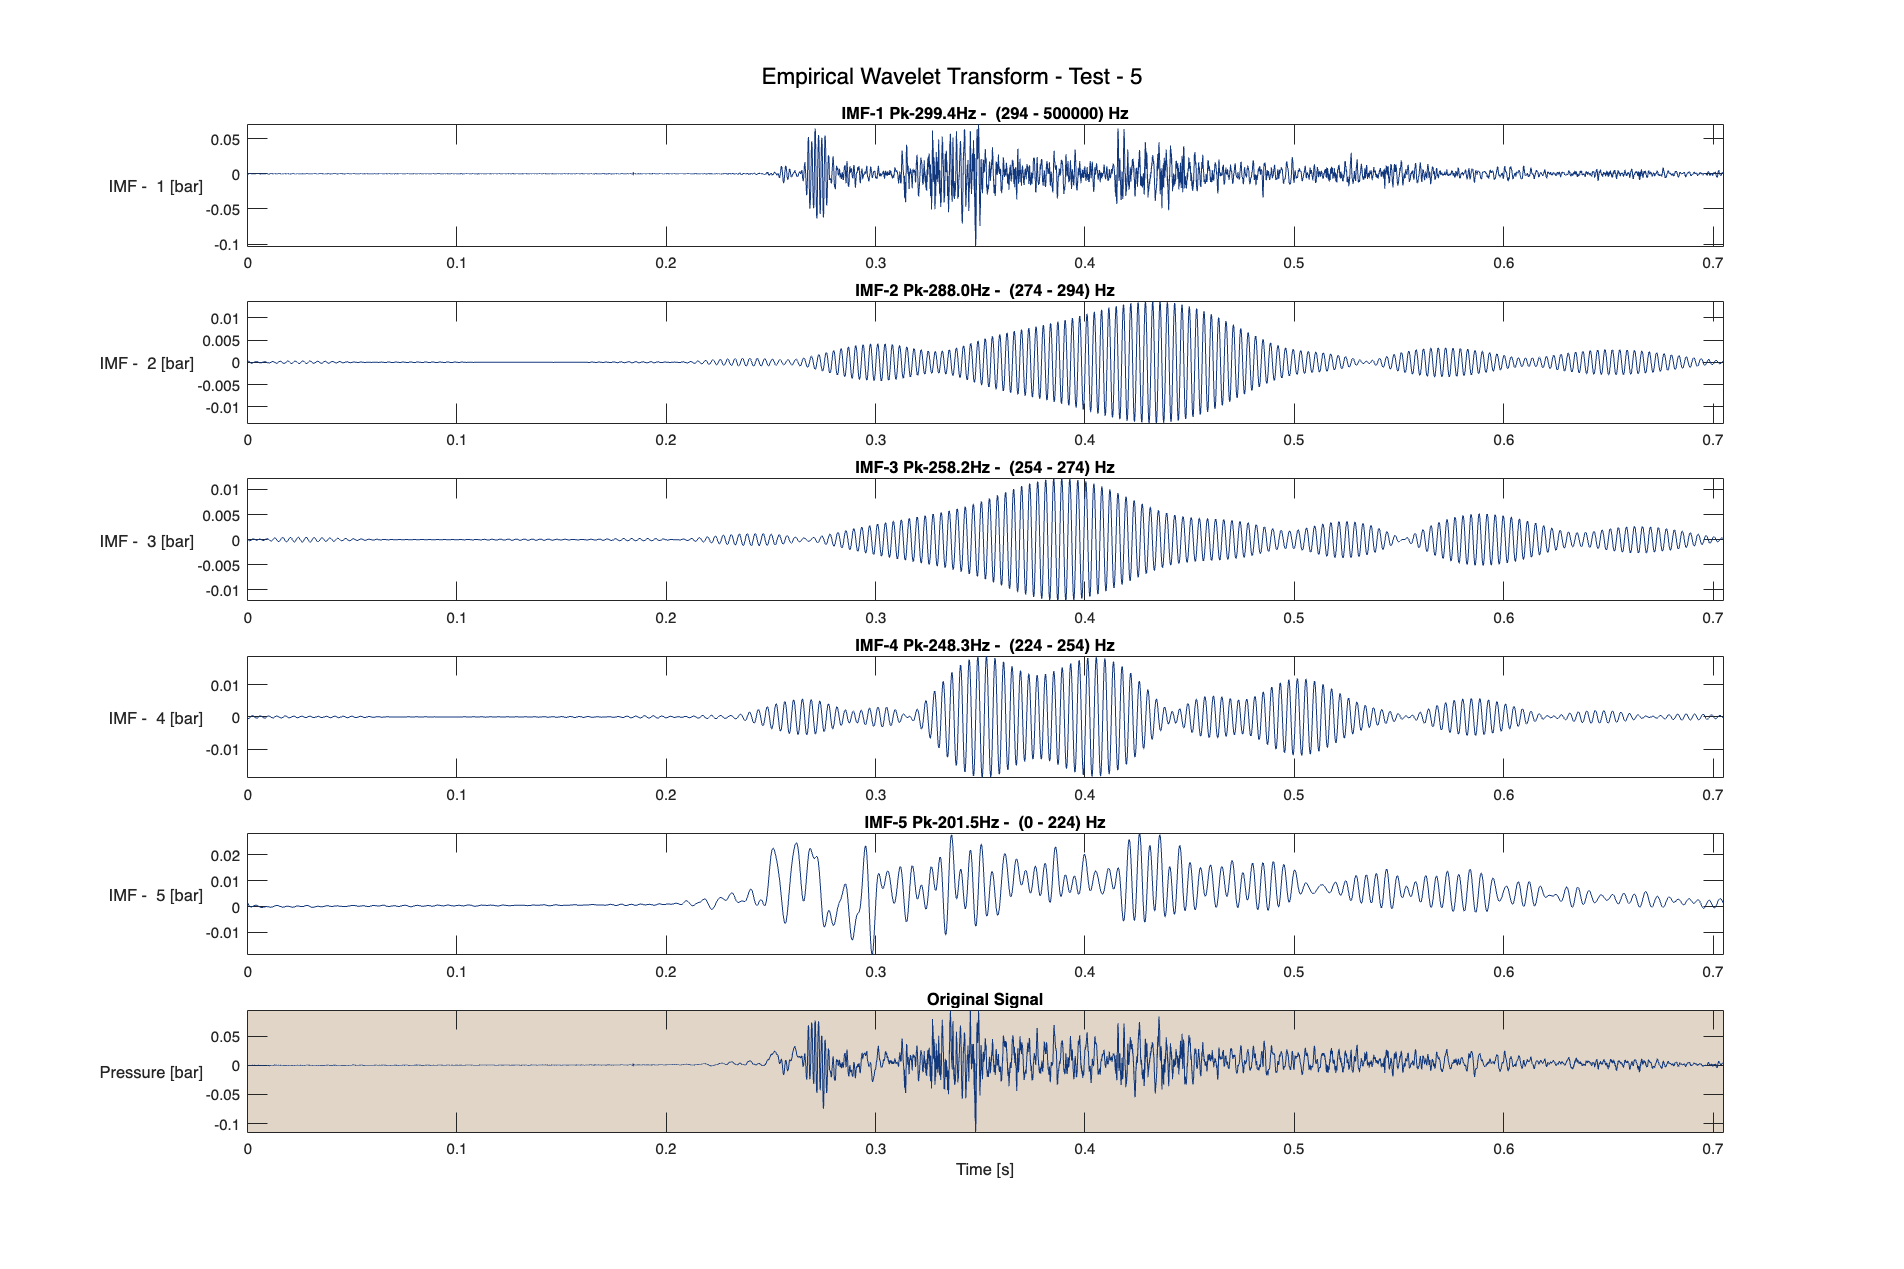

Processing Test 6...


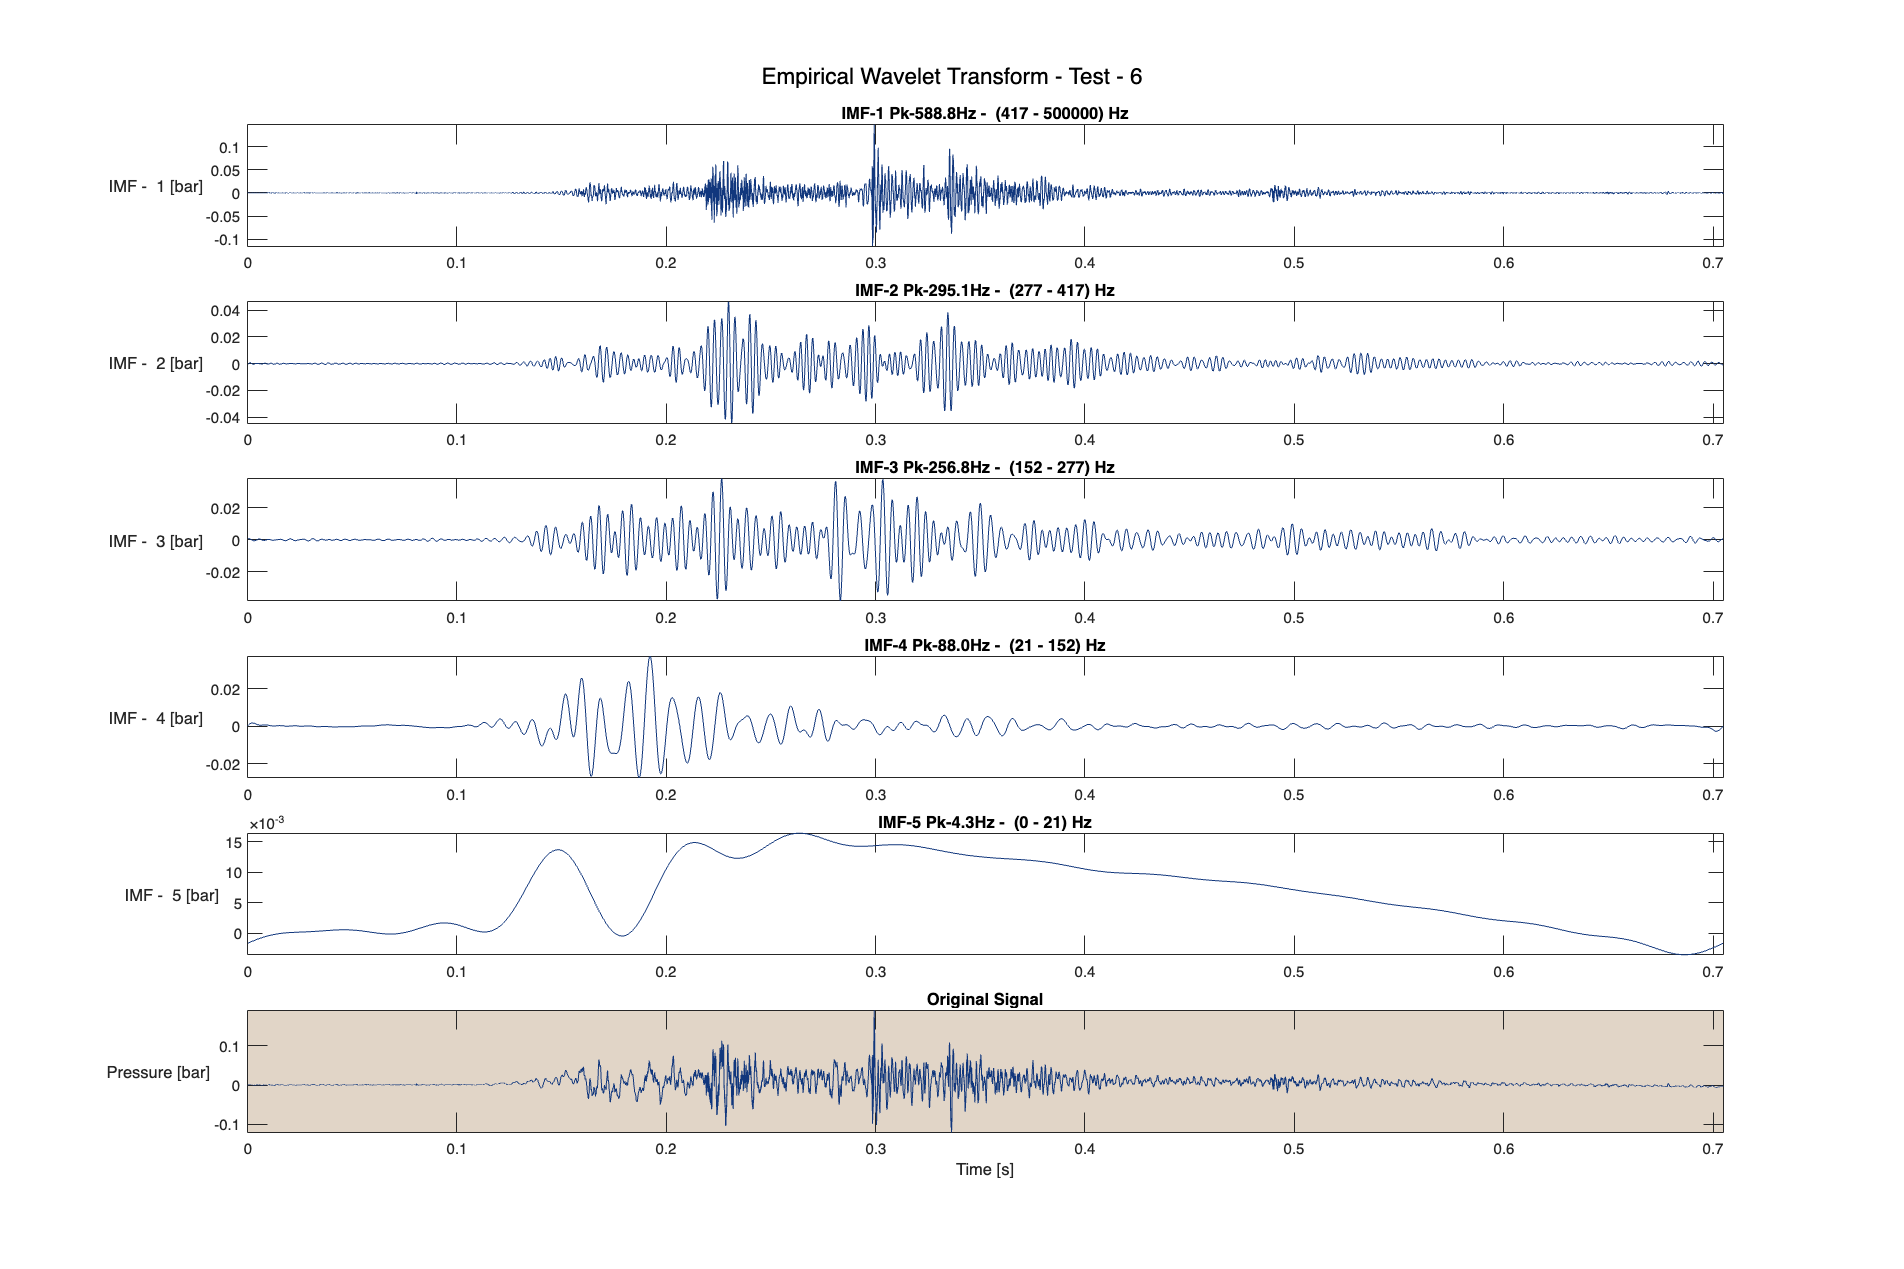

Processing Test 7...


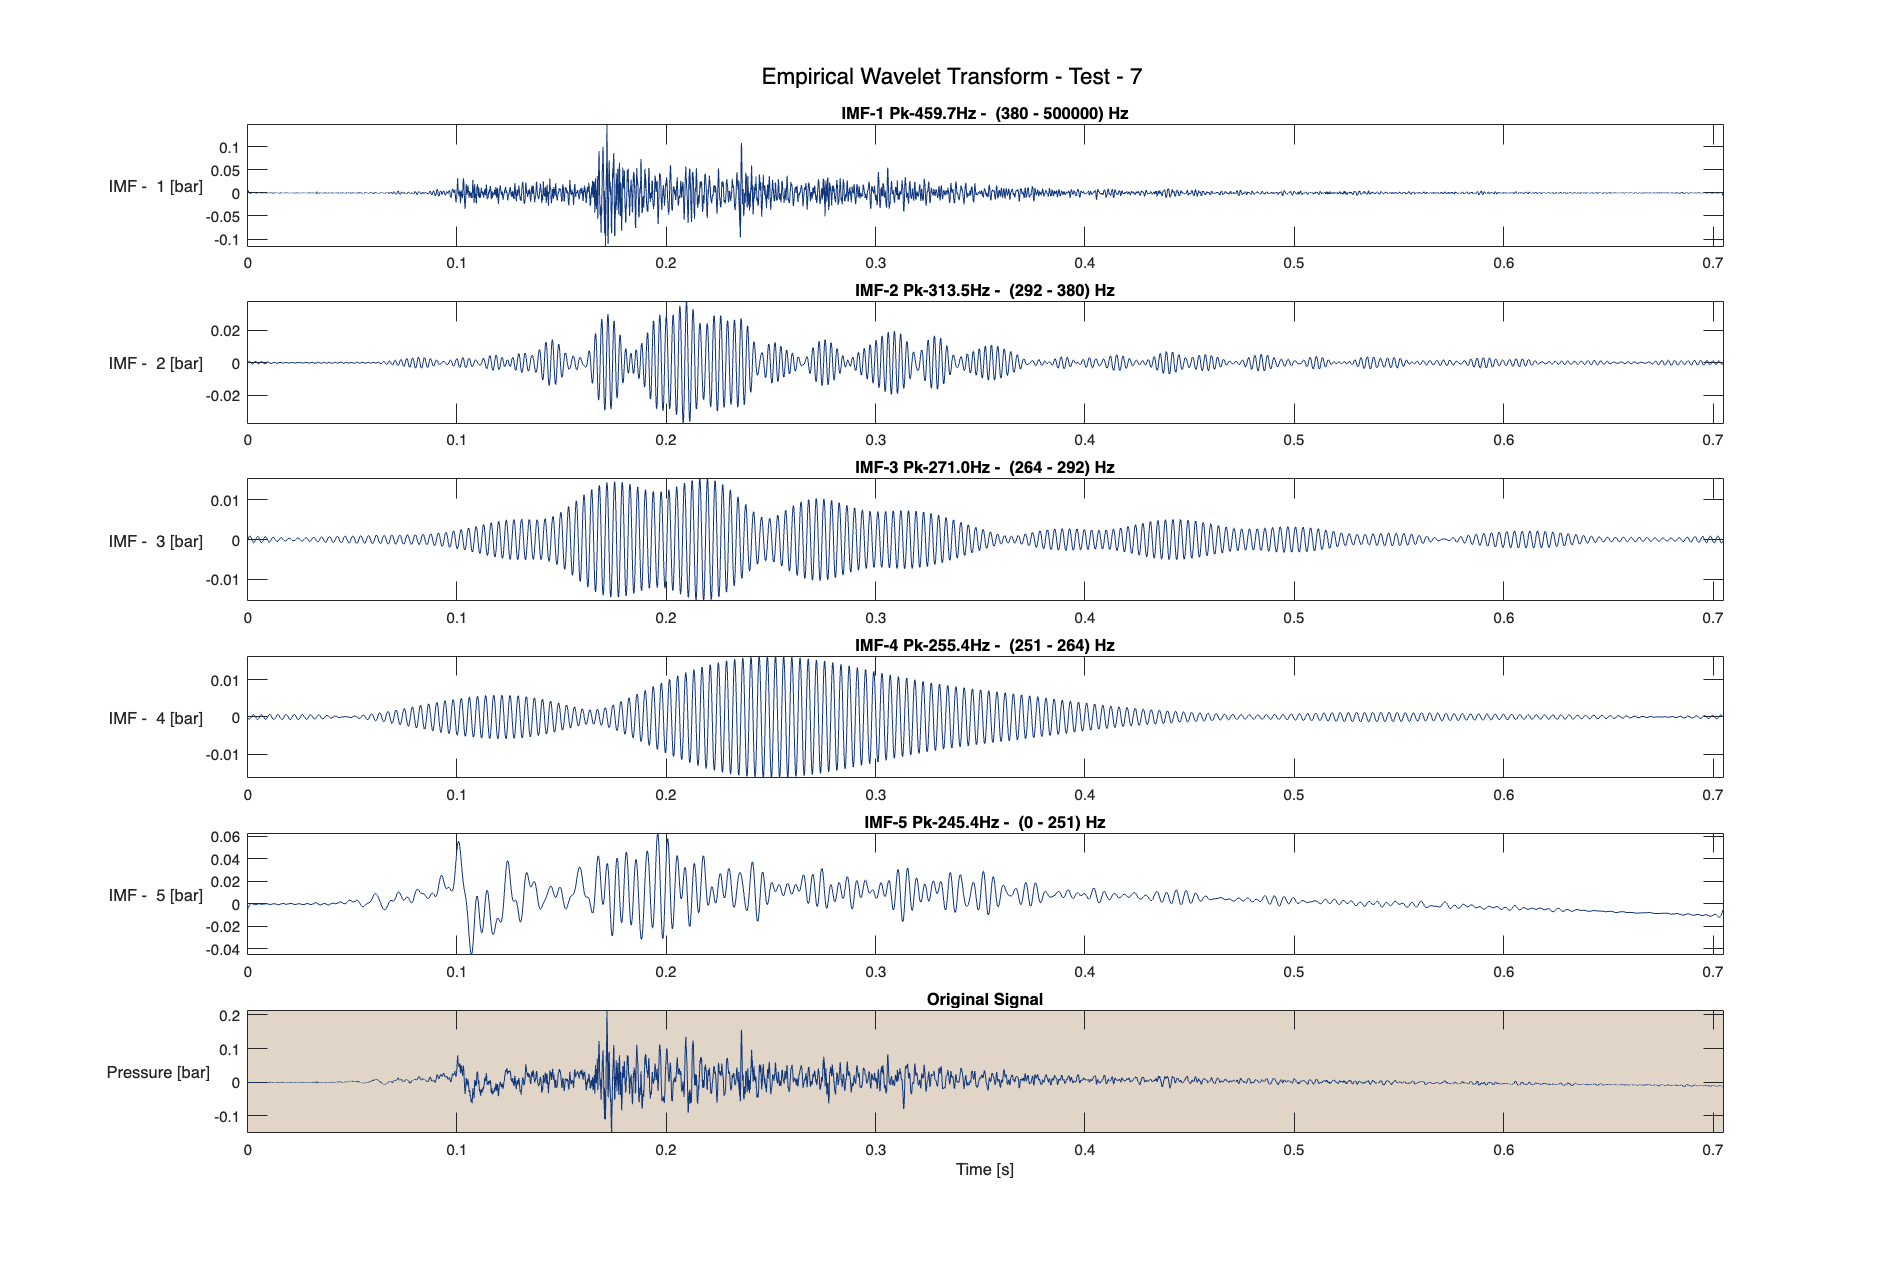

Processing Test 8...


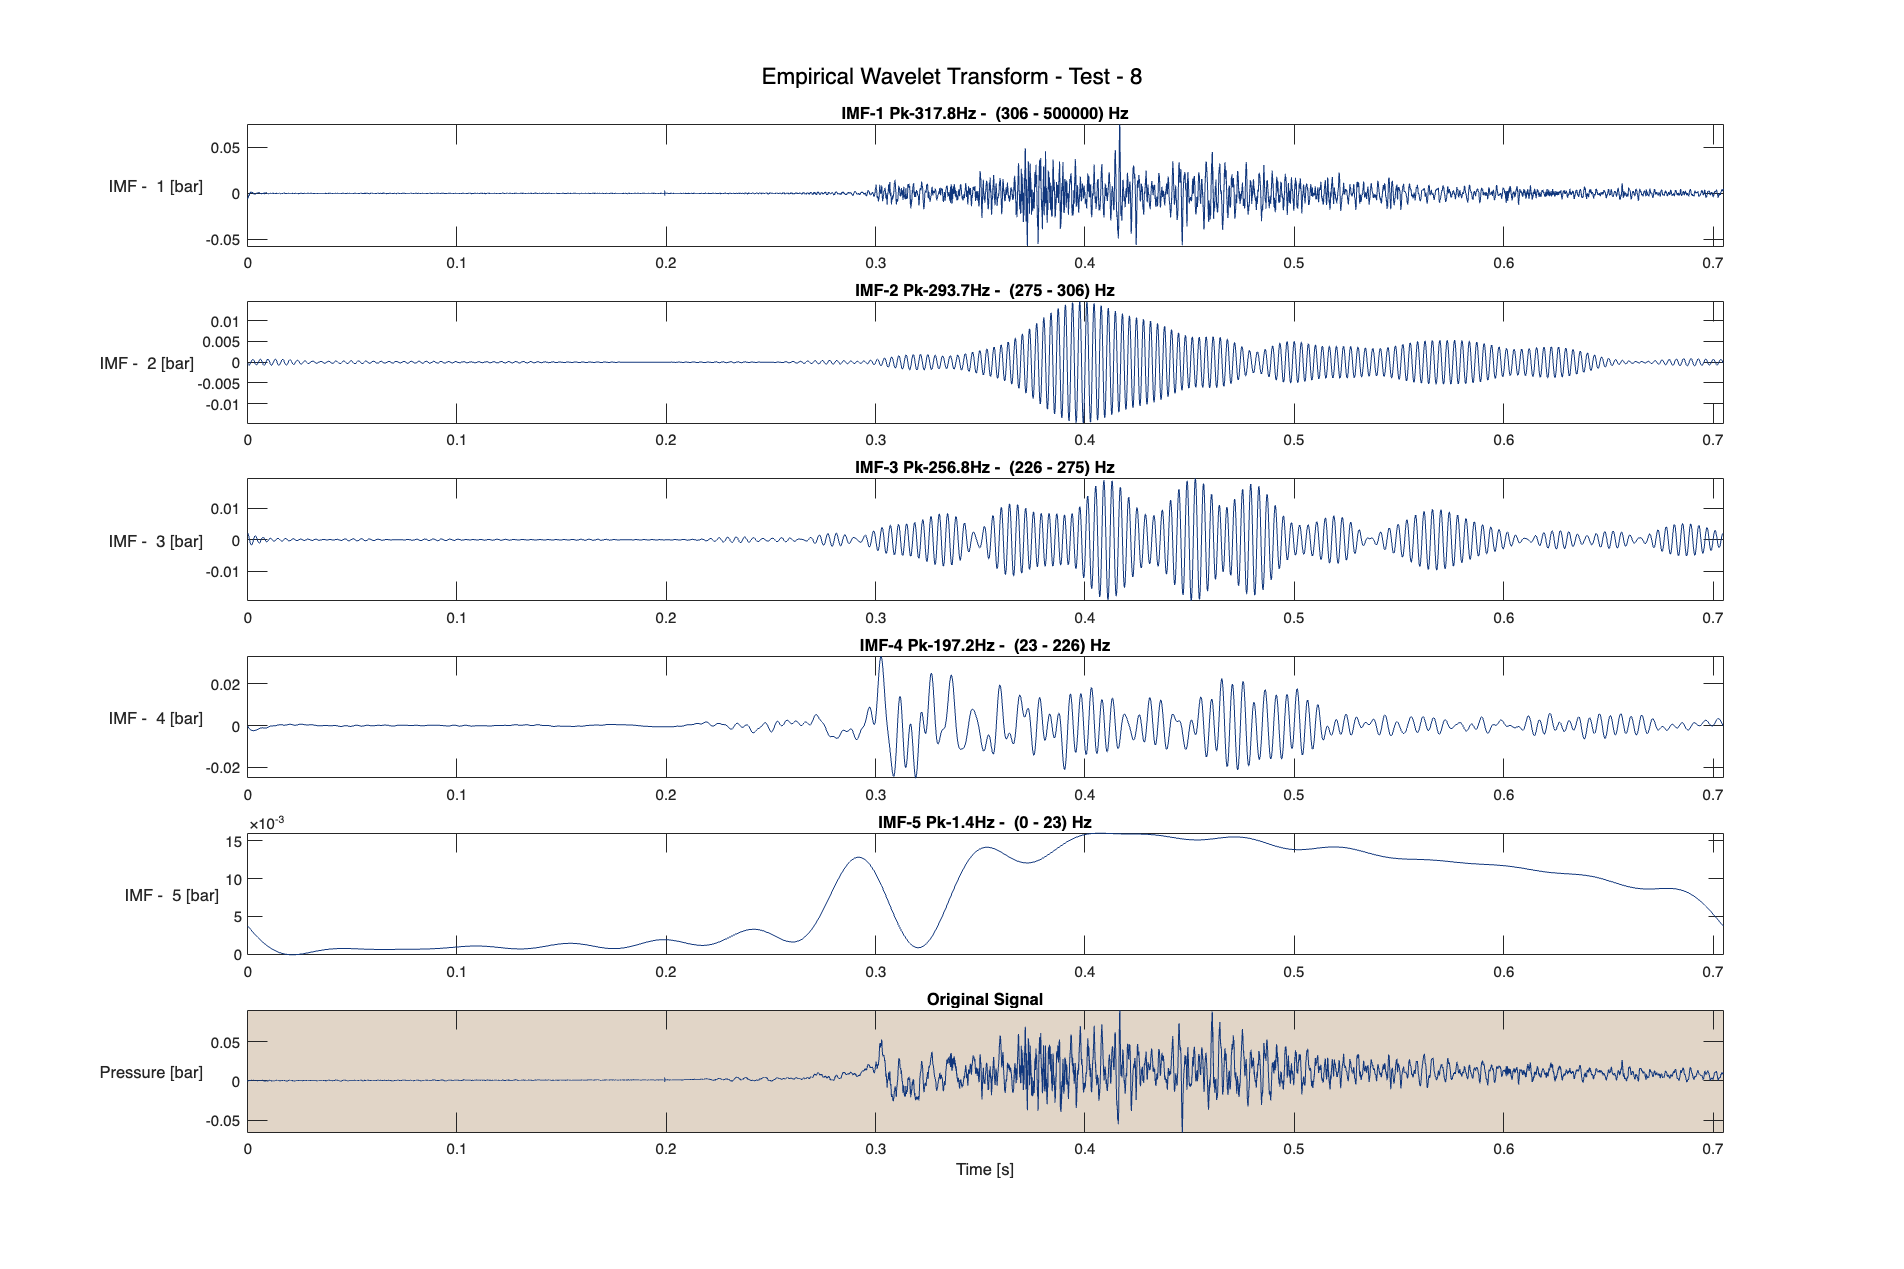

Processing Test 9...


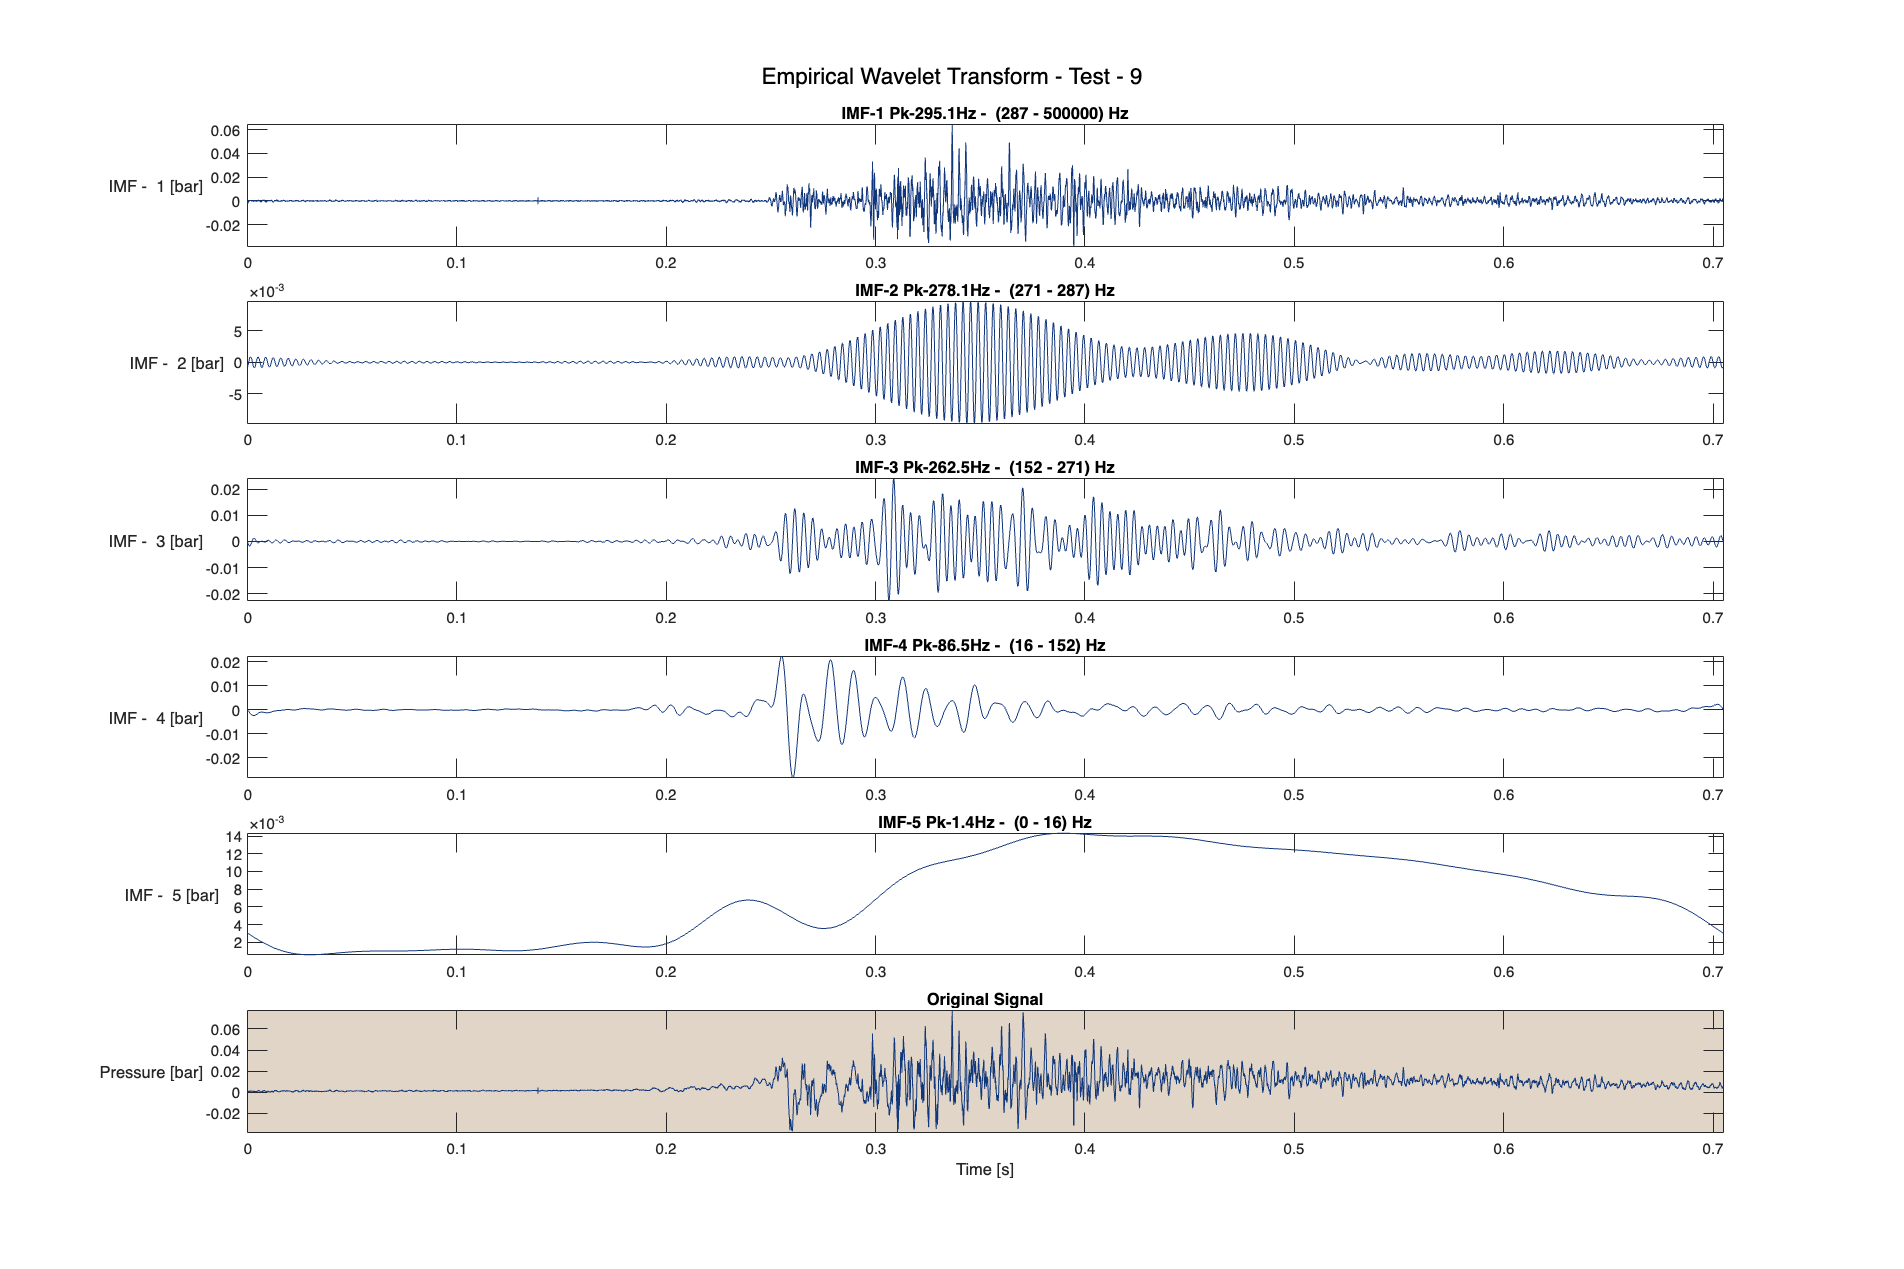

Processing Test 10...


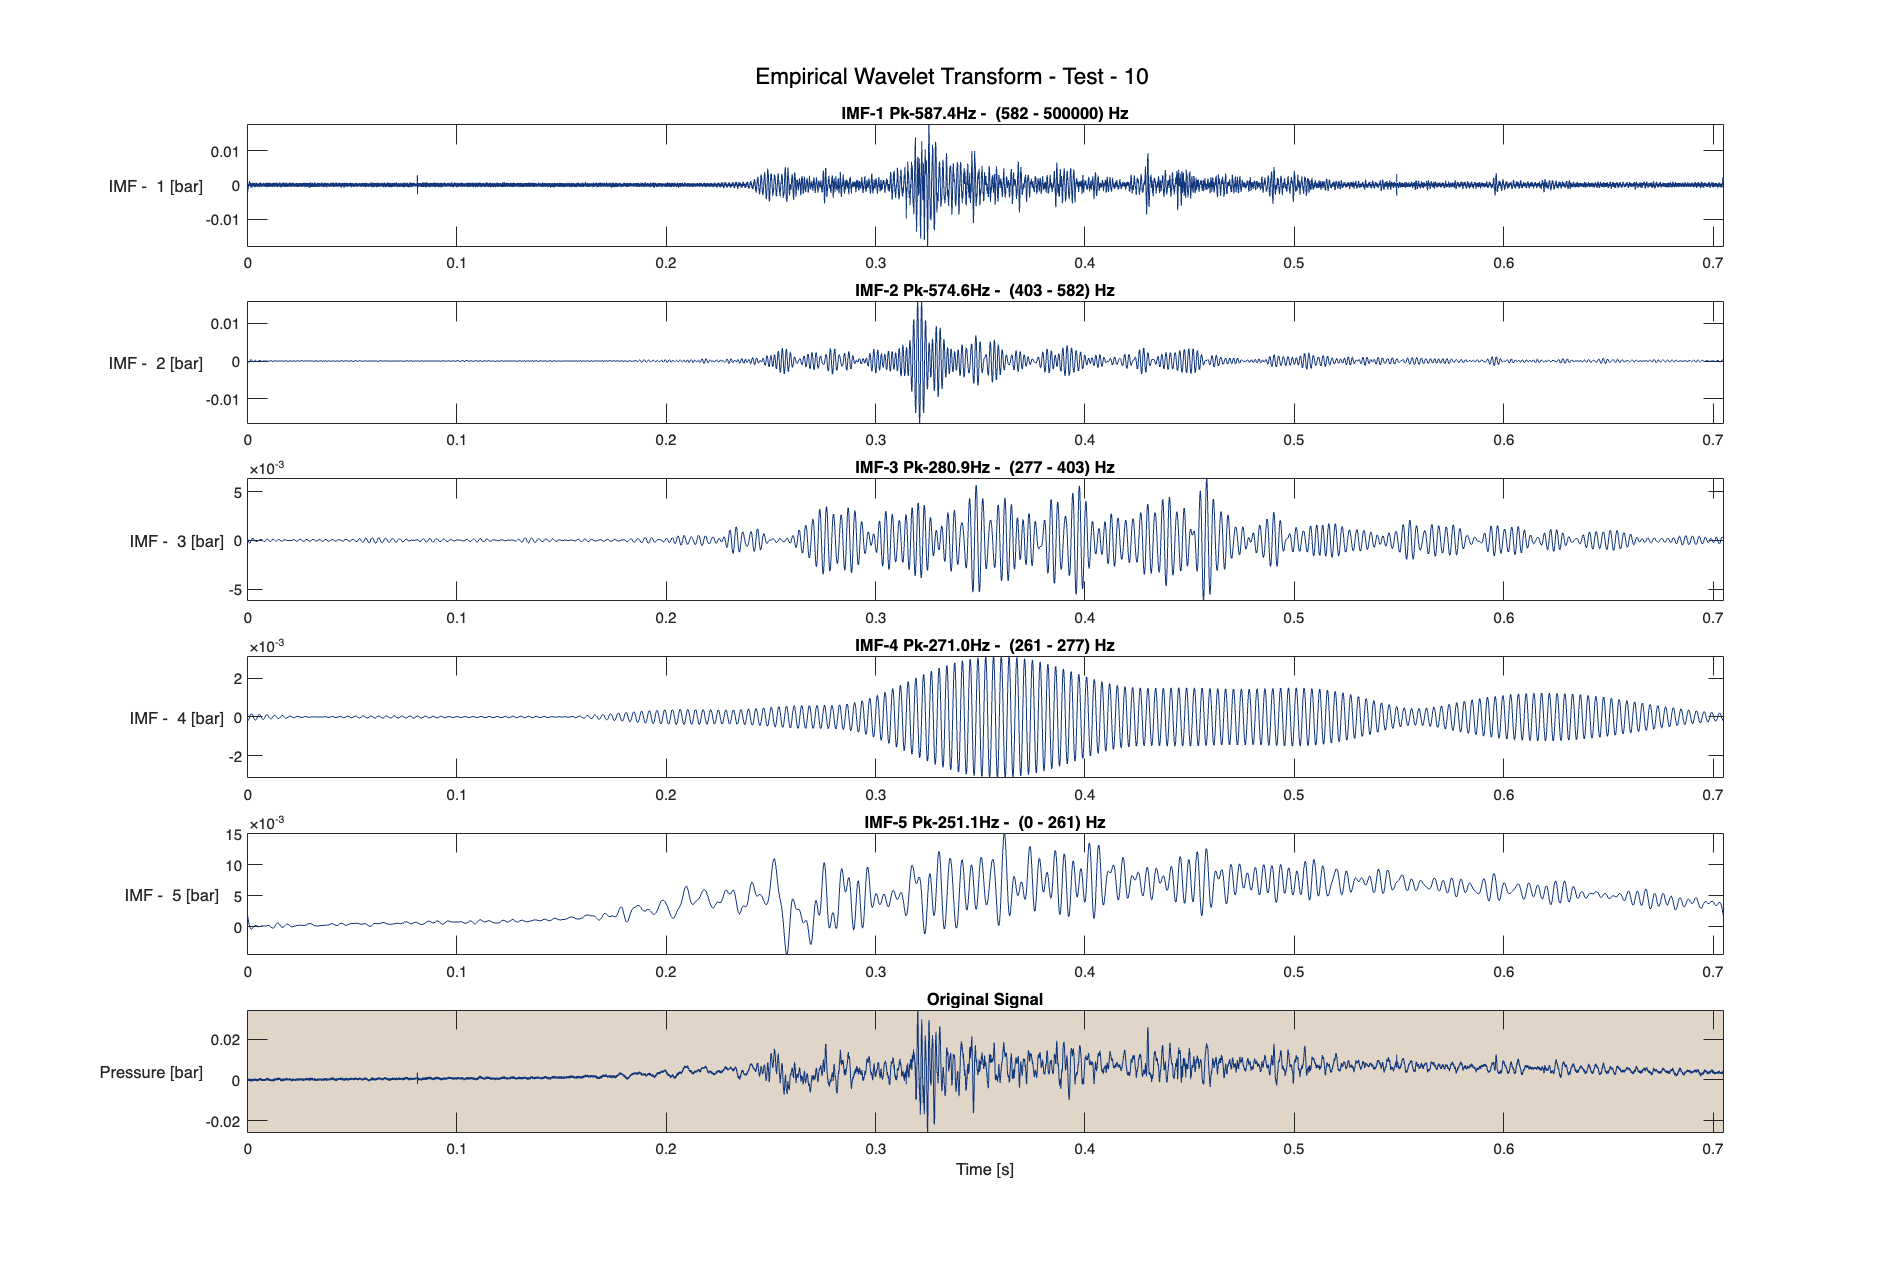

Processing Test 11...


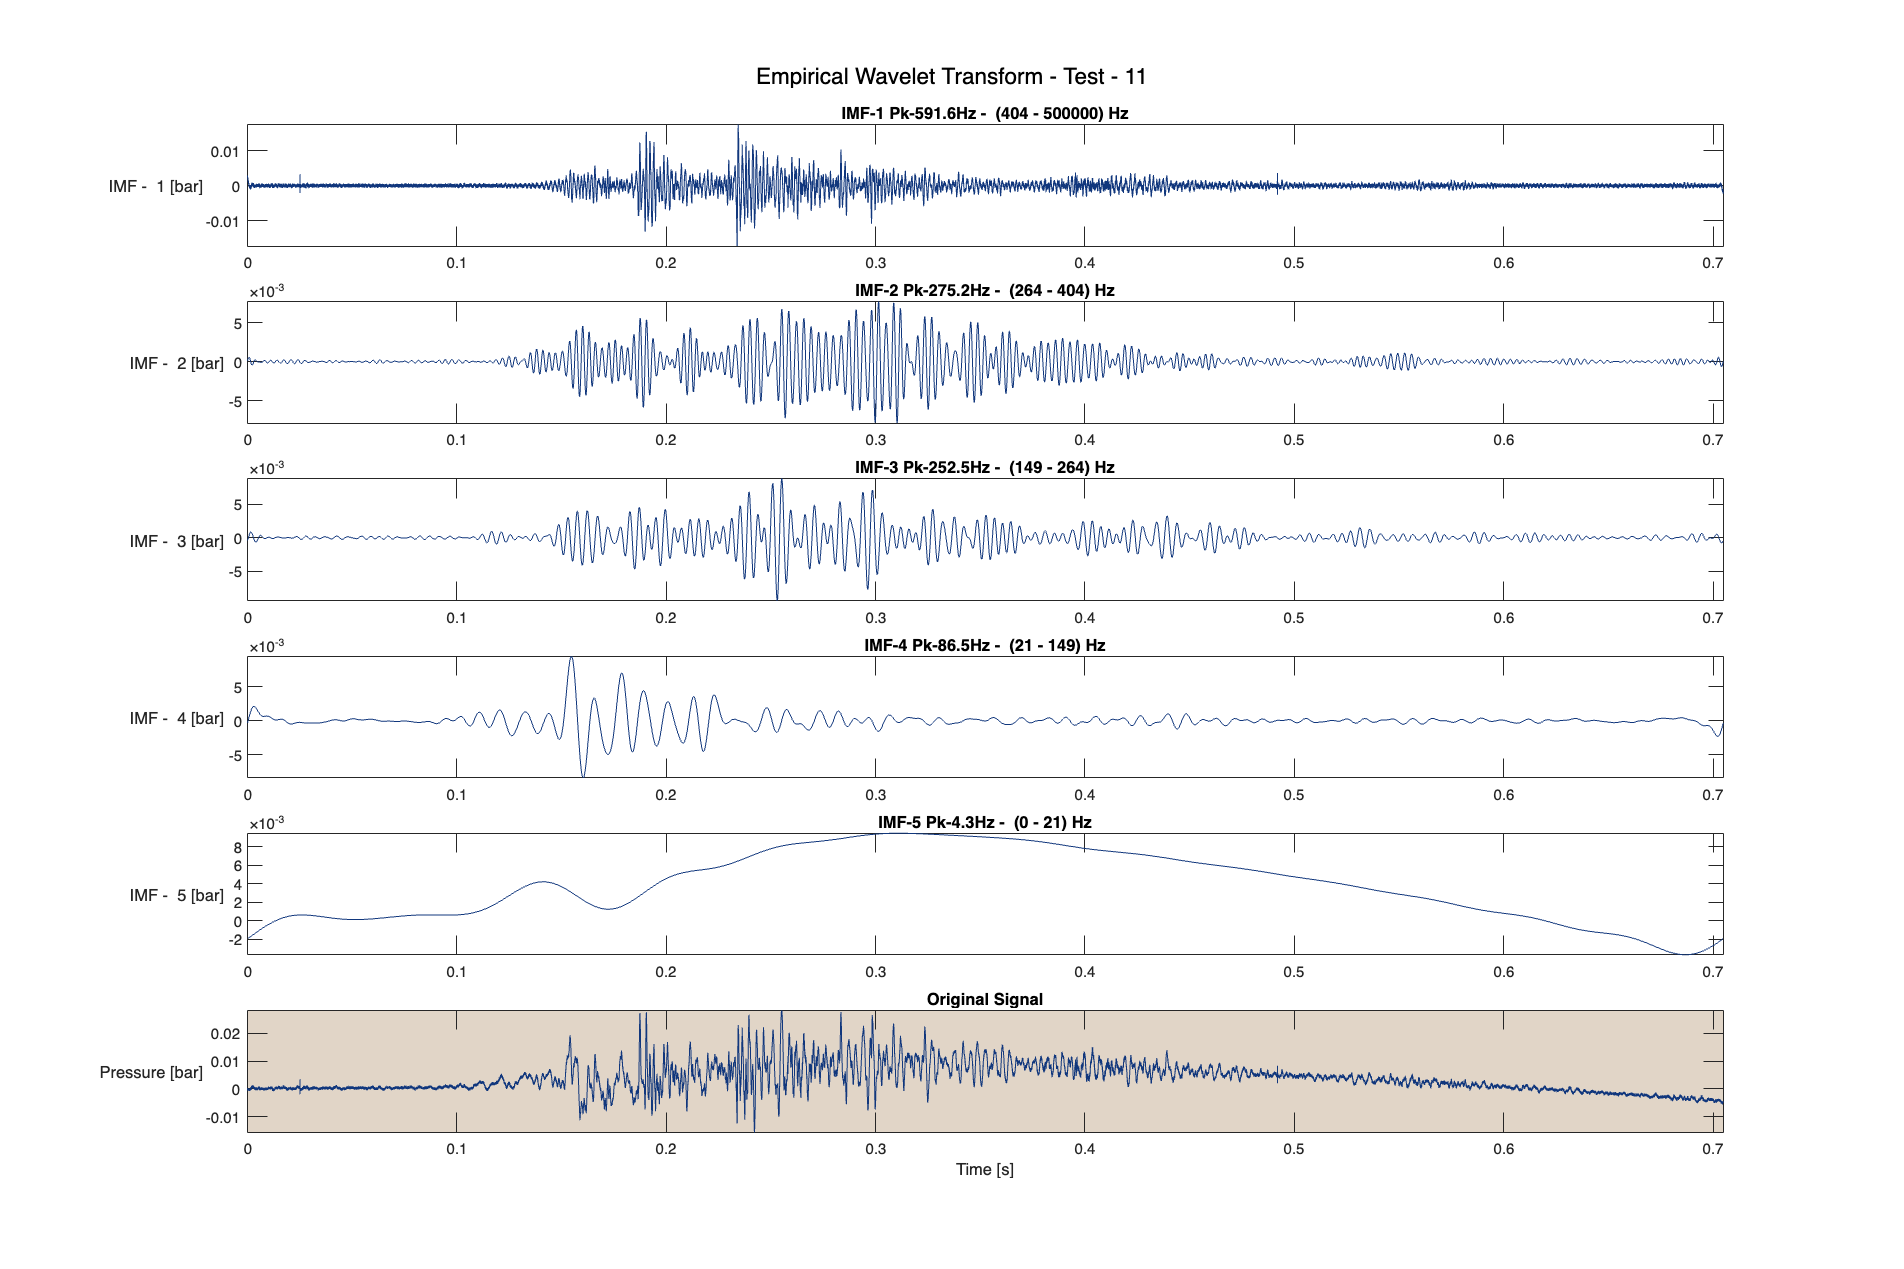

Processing Test 12...


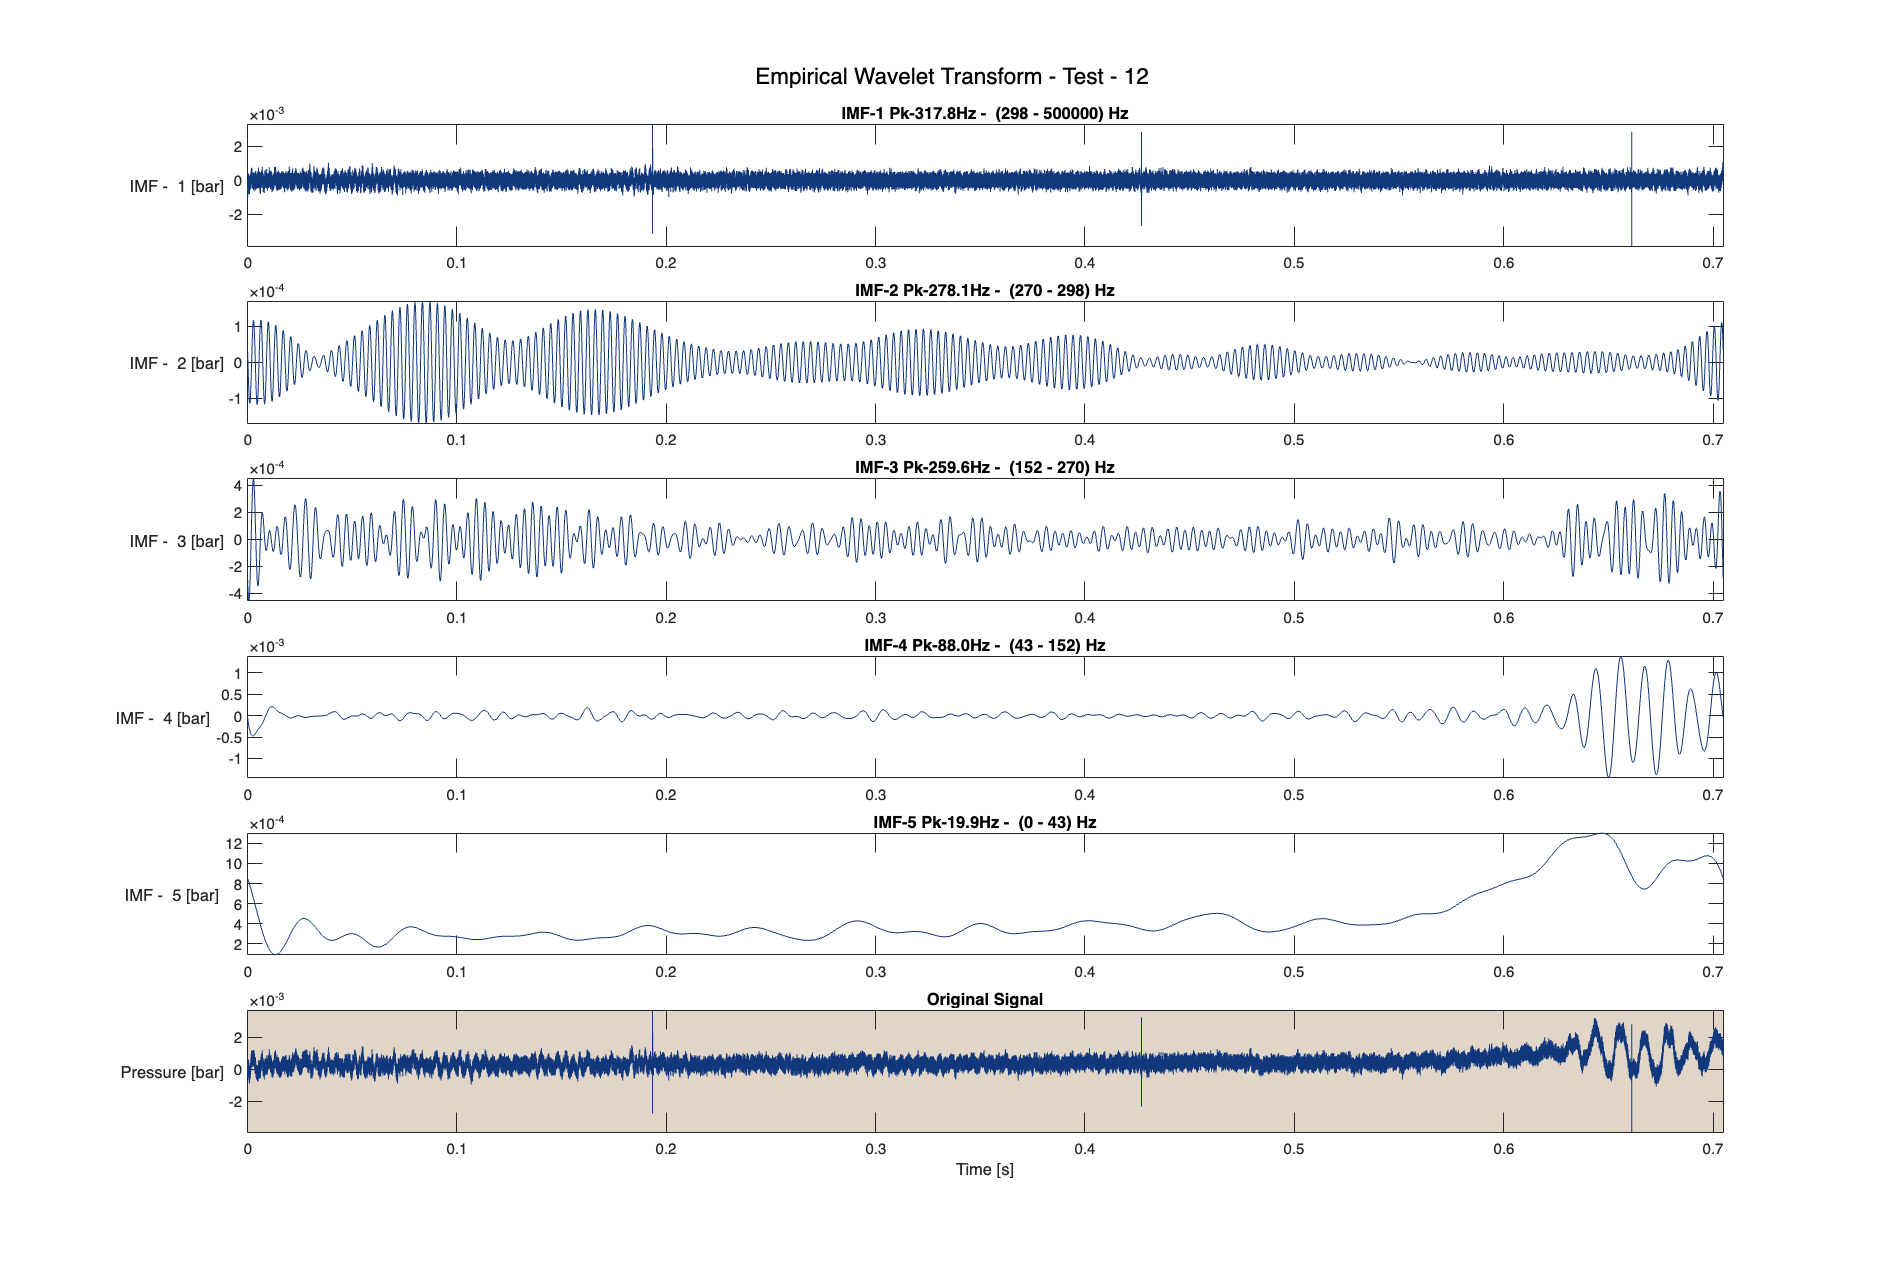

dataPoffsetCorrected = p(:,1:12) - mean(p(1:100,1:12), 1);
% globalMax = max(max(abs(dataPoffsetCorrected))); % Global max across tests
% dataNormalised = dataPoffsetCorrected./globalMax;
% dataPoffsetCorrected = dataPoffsetCorrected./globalMax;
MaxNumPeaks = 5;
testNum = size(dataPoffsetCorrected,2);
results = struct(); % Store results for each test
summaryData = []; % Initialize numerical data matrix
for i = 1:testNum
        fprintf('Processing Test %d...\n', i);
        % Perform EWT on the selected test
        [mra_ewt, cfs, wfb, info] = ewt(dataPoffsetCorrected(:, i), 'MaxNumPeaks',MaxNumPeaks);
        % Convert peak frequencies and passbands to Hz
        PeakFrequencies = Fs * info.PeakFrequencies;
        freqPassbands = Fs * info.FilterBank.Passbands;
        % Store results for each test
        results(i).TestNumber = i;
        results(i).MRA = mra_ewt;
        results(i).Coefficients = cfs;
        results(i).WaveletBank = wfb;
        results(i).PeakFrequencies = PeakFrequencies;
        results(i).Passbands = freqPassbands;
        
        % Append numerical data for structured table
        numModes = length(PeakFrequencies);
        for j = 1:numModes
            summaryData = [summaryData; i, j, PeakFrequencies(j), freqPassbands(j,1), freqPassbands(j,2)];
        end  
figure
    x0=10;
    y0=10;
    width=75;
    height=10 * MaxNumPeaks;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
    signal = subplot(MaxNumPeaks+1,1,MaxNumPeaks+1);
    plot(t,dataPoffsetCorrected(:, i),'Color',AuxFcn_GS.LUBlue);
    
    % p.XTickLabel={};
    signal = gca;
    signal.Color = AuxFcn_GS.LUCopper_Light;
    signal.YLabel.Rotation = 0;
    signal.YLabel.HorizontalAlignment = 'right';
    signal.YLabel.VerticalAlignment = 'middle';
    title('Original Signal')
    sgtitle(['Empirical Wavelet Transform - Test - ',num2str(i)])
    ylabel('Pressure [bar]')
    xlabel('Time [s]')
    axis tight
    for k=1:MaxNumPeaks
        modes = subplot(MaxNumPeaks+1,1,k);
        plot(t,mra_ewt(:,k),'Color',AuxFcn_GS.LUBlue)
        ylabel(['IMF -  ',num2str(k), ' [bar]'])
        modes.YLabel.Rotation = 0;
        modes.YLabel.HorizontalAlignment = 'right';
        modes.YLabel.VerticalAlignment = 'middle';
        % ylabel('Pressure [bar]')
        % title(sprintf("EWT - IMF %d", k))
        title(['IMF-' num2str(k) ' Pk-' num2str(PeakFrequencies(k), '%.1f') 'Hz' ' - ' ' (' num2str(freqPassbands(k,1), '%.0f') ' - ' num2str(freqPassbands(k,2), '%.0f') ') Hz'])
        axis tight
        % if k==MaxNumPeaks
        %     xlabel('Time [s]')
        % else
            s.XTickLabel={};
        % end 
    end
end

    % Convert numerical array to table format
    summaryTable = array2table(summaryData, 'VariableNames', ...
        {'Test Number', 'Mode Number', 'Peak Frequency (Hz)', 'Passband Start (Hz)', 'Passband End (Hz)'});
    
    % Display table in MATLAB
    disp(summaryTable);

    Test Number    Mode Number    Peak Frequency (Hz)    Passband Start (Hz)    Passband End (Hz)
    ___________    ___________    ___________________    ___________________    _________________

         1              1               324.89                 299.35                 5e+05      
         1              2               273.82                 268.14                299.35      
         1              3               261.05                 252.53                268.14      
         1              4               244.02                 222.74                252.53      
         1              5               201.46                      0                222.74      
         2              1                583.1                 429.88                 5e+05      
         2              2               314.9


    % Save results in the workspace
    assignin('base', 'EWT_Results', results);
    assignin('base', 'EWT_SummaryTable', summaryTable);
    fprintf('EWT analysis completed for selected tests.\n');

EWT analysis completed for selected tests.


Plot the magnitude spectrum of the signal, and the filter bank. The locations of the peaks determine the filter passbands.

% figure
% f = 0:Fs/length(data):Fs-1/length(data);
% plot(f,wfb)
% ylabel('Magnitude')
% grid on
% yyaxis right
% plot(f,abs(fft(data)),'k--','linewidth',1.5)
% ylabel('Magnitude')
% xlabel('Hz')

Verify that summing the MRA components results in perfect reconstruction of the signal.

resid_mra_ewt = max(abs(data-sum(mra_ewt,2)))

resid_mra_ewt =    123.8833e-003


Verify energy preservation of the EWT analysis coefficients.

cfsenergy = sum(sum(abs(cfs).^2));
[cfsenergy norm(data,2)^2]

ans =    282.2401e-003   246.7110e+000


MRA_all = {results([6 7]).MRA}; % Convert struct array to cell array
MRA_5 = cell2mat(cellfun(@(x) x(:,5), MRA_all, 'UniformOutput', false)); 